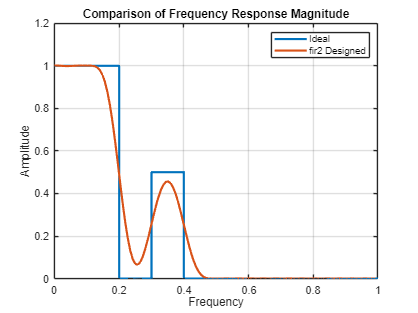

% FIR Filter Design and Frequency Response Analysis
% --------------------------------------------------
% This script designs a Finite Impulse Response (FIR) filter using the fir2 
% function, which allows for the specification of an arbitrary piecewise 
% linear frequency response. It then plots the designed filter's frequency 
% response alongside the ideal frequency response for comparison.

% Define the filter order
n = 51;

% Define the frequency and magnitude vectors
f = [0 0.2 0.2 0.3 0.3 0.4 0.4 1];
m = [1 1 0 0 0.5 0.5 0 0];

% Design the FIR filter using the fir2 function
b = fir2(n-1, f, m);

% Compute the frequency response of the designed filter
[h, w] = freqz(b, 1, 128);

% Plot the ideal and designed frequency responses
figure;
plot(f, m, 'LineWidth', 2);          % Plot the ideal response
hold on;
plot(w/pi, abs(h), 'LineWidth', 2);  % Plot the designed response
grid on;

% Add legend and labels
legend('Ideal', 'fir2 Designed');
title('Comparison of Frequency Response Magnitude');
xlabel('Frequency');
ylabel('Amplitude');

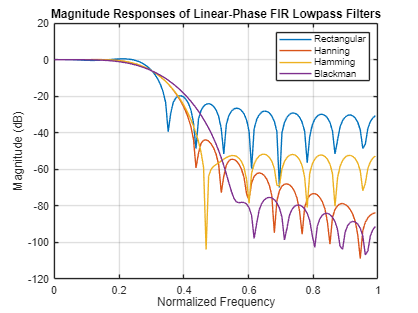


% FIR Lowpass Filter Design and Frequency Response Comparison
% -----------------------------------------------------------
% This script designs Finite Impulse Response (FIR) lowpass filters using 
% different window functions. It then computes and plots the magnitude 
% response of each filter for comparison.

% Define the filter parameters
L = 23;          % Filter length
wC = 0.3*pi;     % Band edge

% Design the filters using different windows
b1 = fir1(L-1, wC/pi, boxcar(L), 'scale');
b2 = fir1(L-1, wC/pi, hanning(L), 'scale');
b3 = fir1(L-1, wC/pi, hamming(L), 'scale');
b4 = fir1(L-1, wC/pi, blackman(L), 'scale');

% Compute the frequency response of the filters
[H1, W] = freqz(b1, 1, 128);
[H2, W] = freqz(b2, 1, 128);
[H3, W] = freqz(b3, 1, 128);
[H4, W] = freqz(b4, 1, 128);

% Plot the magnitude response of the filters
figure;

% Plot the frequency responses on the same graph for comparison
plot(W/pi, 20*log10(abs([H1 H2 H3 H4]))); grid on;

% Add labels and title to the plot
xlabel('Normalized Frequency');
ylabel('Magnitude (dB)');
legend('Rectangular', 'Hanning', 'Hamming', 'Blackman', 'Location', 'northeast');
title('Magnitude Responses of Linear-Phase FIR Lowpass Filters');

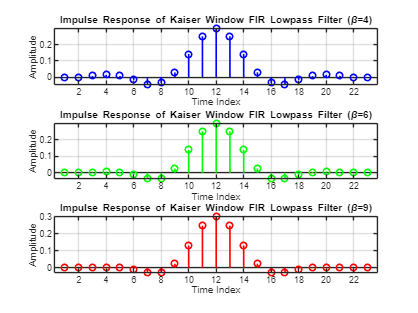

% FIR Filter Design and Frequency Response Analysis
% --------------------------------------------------
% This script designs a length-23 linear-phase FIR lowpass filter
% with a band edge of wC = 0.3*pi using a Kaiser window with β = 4, 6, and 9.
% It then plots the designed filter's impulse response, amplitude response,
% and zero locations.

% Filter specifications
N = 23;
wc = 0.3*pi;

% Kaiser window design parameters
beta = [4, 6, 9];

% Design the filters using the Kaiser window
b1 = fir1(N-1, wc/pi, kaiser(N, beta(1)));
b2 = fir1(N-1, wc/pi, kaiser(N, beta(2)));
b3 = fir1(N-1, wc/pi, kaiser(N, beta(3)));

% Plot the impulse response of the filters
figure;
subplot(3,1,1);
stem(b1, 'b', 'LineWidth', 1.5); 
title('Impulse Response of Kaiser Window FIR Lowpass Filter (\beta=4)');
xlabel('Time Index'); ylabel('Amplitude');
grid on;

subplot(3,1,2);
stem(b2, 'g', 'LineWidth', 1.5); 
title('Impulse Response of Kaiser Window FIR Lowpass Filter (\beta=6)');
xlabel('Time Index'); ylabel('Amplitude');
grid on;

subplot(3,1,3);
stem(b3, 'r', 'LineWidth', 1.5); 
title('Impulse Response of Kaiser Window FIR Lowpass Filter (\beta=9)');
xlabel('Time Index'); ylabel('Amplitude');
grid on;

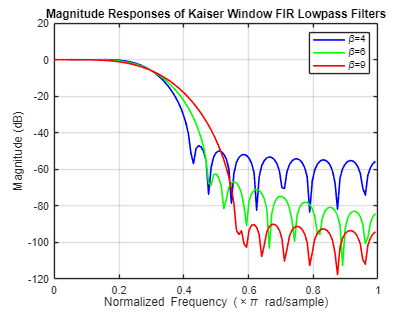


% Compute and plot the amplitude response of the filters
[H1, W1] = freqz(b1, 1, 128);
[H2, W2] = freqz(b2, 1, 128);
[H3, W3] = freqz(b3, 1, 128);
figure;
plot(W1/pi, 20*log10(abs(H1)), 'b', 'LineWidth', 1.5); hold on;
plot(W2/pi, 20*log10(abs(H2)), 'g', 'LineWidth', 1.5);
plot(W3/pi, 20*log10(abs(H3)), 'r', 'LineWidth', 1.5);
grid on;
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude (dB)');
legend('\beta=4', '\beta=6', '\beta=9', 'Location', 'northeast');
title('Magnitude Responses of Kaiser Window FIR Lowpass Filters');

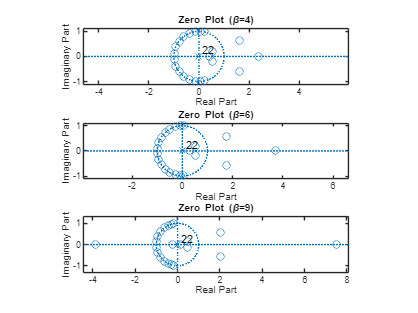


% Plot the zero locations of the filters
figure;
subplot(3,1,1);
zplane(b1, 1); title('Zero Plot (\beta=4)');

subplot(3,1,2);
zplane(b2, 1); title('Zero Plot (\beta=6)');

subplot(3,1,3);
zplane(b3, 1); title('Zero Plot (\beta=9)');